# Master Stiffness Matrix and Body Load Vector for the Reissner-Mindlin Plate using Page-Wise Computations and `sparse`-Matrices

Computation of the master stiffness matrix and master load vector corresponding to the standard Reissner-Mindlin plate formulation with three degrees of freedom per node $\left(w,\beta_x ,\beta_y \right)$, the vertical deflection and two rotations of the plate's cross section around the $X$- and the $Y$-axis, respectively, using [page-wise](https://blogs.mathworks.com/loren/2021/01/14/paged-matrix-functions/) computation of the element stiffness matrices [`sparse`](https://www.mathworks.com/help/matlab/ref/sparse.html)-matrices for the assembly. A schematic of this workflow is shown in the following figure:

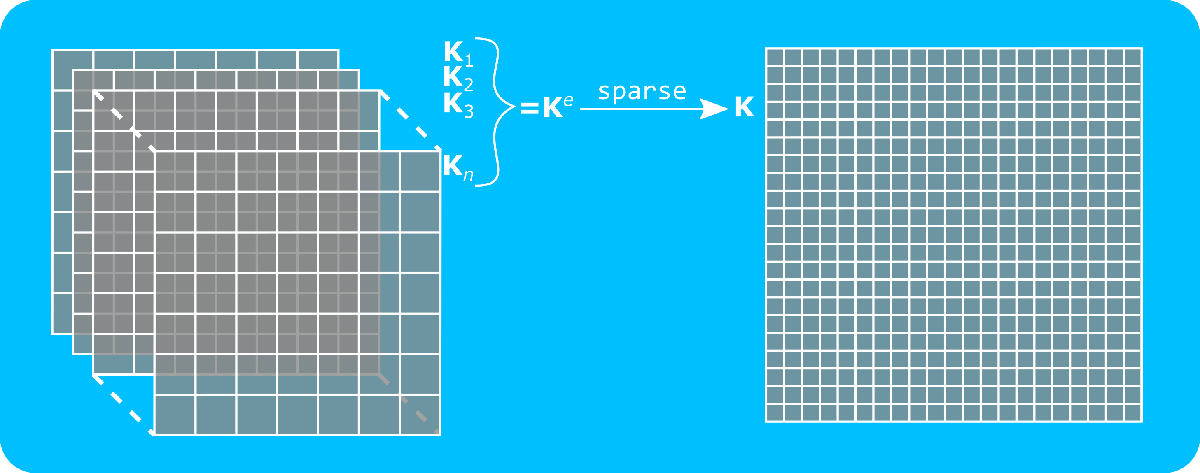

The master stiffness matrix and master load vector for the standard Reissner-Mindlin plate are given by the following relations:


$$\begin{array}{ll}
\mathbf{K} = \int_{A} \mathbf{B}_{\text{s}}^{\text{T}} \mathbf{C}_{\text{s}} \mathbf{B}_{\text{s}} \, \text{d} A+ \int_{A} \mathbf{B}_{\text{b}}^{\text{T}} \mathbf{C}_{\text{b}} \mathbf{B}_{\text{b}} \: \text{d} A , & \text{(1.1)} \\
\mathbf{F} = \int_{A} \mathbf{N}^{\text{T}} \left[ \begin{array}{c} \bar{p} \\ \bar{m}_x \\ \bar{m}_y \end{array} \right] \: \text{d} A + \int_{\subset\partial A} \mathbf{N}^{\text{T}} \left[ \begin{array}{c} \bar{P} \\ \bar{M}_x \\ \bar{M}_y \end{array} \right] \: \text{d} \partial A . & \text{(1.2)}
\end{array}$$


function [K, F] =  ...
    computeMasterStiffMatrixandForceVctReissnerMindlinPlatePageWise ...
    (msh, computeBasisFunctionsAndDerivs, ~, propStr)

## Function Description

Computation of the master stiffness matrix and the master load vector for a plate using the two-dimensional Reissner-Mindlin plate theory with three degrees of freedom per node $\left(w,\beta_x ,\beta_y \right)$, the vertical deflection and two rotations of the plate's cross section around the $X$- and the $Y$-axis, respectively, using a page-wise computation for the element stiffness matrices and subsequently `sparse`-matrices for the assembly.

**                                                                  Input :**

                                                                         `X` : Array containing the nodal coordinates of the nodes in the element

                `computeBasisFunctionsAndDerivs` : Function handle to the computation of the basis functions

                                                             `propStr` : Structure containing the following fields,

                                                                                 `.t` : Thickness

                                                                           `.pBar` : Distributed load

                                                                         `.mxBar` : Distributed moment around x-axis

                                                                         `.myBar` : Distributed moment around y-axis

                                                                                 `.E` : Young's modulus

                                                                               `.nu` : Poisson's ratio

                                                                                 `.G` : Shear modulus

                                                                                 `.D` : Plate's stiffness

                                                                         `.alpha` : Shear correction factor

**                                                      Output :**

                                                                `K` : Master stiffness matrix of a Reissner-Mindlin plate (`sparse`)

                                                                `F` : Master force vector of a Reissner-Mindlin plate (`sparse`)

## Function Implementation

### Input validation

    arguments
        msh (1,1) struct {mustHaveNodesAndElements}
        computeBasisFunctionsAndDerivs (1,1) function_handle
        ~
        propStr (1,1) struct {mustHaveReissnerMindlinPlateProperties}
    end

### Check input

    if ~strcmp(func2str(computeBasisFunctionsAndDerivs), ...
            "computeBilinearBasisFunctionsAndFirstDerivatives") && ...
            ~strcmp(func2str(computeBasisFunctionsAndDerivs), ...
            "computeBiquadraticBasisFunctionsAndFirstDerivatives")
        error("Input 'computeBasisFunctionsAndDerivs' is defined as %s but only " + ...
            "values 'computeBilinearBasisFunctionsAndFirstDerivatives' and " + ...
            "'computeBiquadraticBasisFunctionsAndFirstDerivatives' are supported", ...
            computeBasisFunctionsAndDerivs);
    end

### Read input

    numDOFsPerNode = 3; % one vertical displacement and two cross-sectional rotations
    numNodes = height(msh.nodes);
    numDOFs = numNodes*numDOFsPerNode;
    numEl = height(msh.elements);
    numNodesEl = width(msh.elements);
    numDOFsEl = numDOFsPerNode*numNodesEl;
    nodesElPageWise = vertcat(reshape(pagetranspose(reshape(msh.nodes(msh.elements, 1), ...
        [], numNodesEl)), 1, [], numEl), ...
        reshape(pagetranspose(reshape(msh.nodes(msh.elements, 2), [], numNodesEl)), ...
        1, [], numEl));

### Initialization of the page-wise element stiffness matrices and load vectors

    KePageWise = zeros(numDOFsEl, numDOFsEl, numEl);
    FePageWise = zeros(numDOFsEl, 1, numEl);

### Construction of the page-wise Element Freedom Tables (EFTs)

    EFT = squeeze(reshape(vertcat(3*reshape(transpose(msh.elements), 1, numNodesEl, ...
        numEl)-2, 3*reshape(transpose(msh.elements), 1, numNodesEl, numEl)-1, ...
        3*reshape(transpose(msh.elements), 1, numNodesEl, numEl)), numDOFsEl, 1, ...
        numEl));

### Construction of the page-wise material matrices

    C = [propStr.alpha*propStr.G*propStr.t 0                                 0                    0                     0
         0                                 propStr.alpha*propStr.G*propStr.t 0                    0                     0
         0                                 0                                 propStr.D            propStr.nu*propStr.D  0
         0                                 0                                 propStr.nu*propStr.D propStr.D             0
         0                                 0                                 0                    0                     propStr.D/2*(1 - propStr.nu)];  
    CPageWise = repmat(C, 1, 1, numEl);

### Gauss points and weights for the numerical integration

    if strcmp(func2str(computeBasisFunctionsAndDerivs), ...
            "computeBilinearBasisFunctionsAndFirstDerivatives")
        numGP = 2;
    elseif strcmp(func2str(computeBasisFunctionsAndDerivs), ...
            "computeBiquadraticBasisFunctionsAndFirstDerivatives")
        numGP = 4;
    end
    [xiGP, GWXi] = getGaussPointsAndWeightsOverUnitDomain(numGP);
    [etaGP, GWEta] = getGaussPointsAndWeightsOverUnitDomain(numGP);

### Loop over all the Gauss points for the numerical integration

for jj = 1:height(GWEta)
    for ii = 1:height(GWXi)

#### Basis functions at the Gauss point

        [dN, ~] = computeBasisFunctionsAndDerivs(xiGP(ii), etaGP(jj));
        numBF = height(dN);
        if numBF ~= numNodesEl
            error("Numner of nodes does not match the number of basis functions");
        end
        dNPageWise = repmat(dN, 1, 1, numEl);

#### Pagewise basis functions' matrix


$$\mathbf{N} = \left[ \begin{array}{ccccccc} N_1(\xi,\eta) & 0 & 0 & \cdots &  N_n(\xi,\eta) & 0 & 0 \\ 0 & N_1(\xi,\eta) & 0 & \cdots &  0 & N_n(\xi,\eta) & 0 \\
0 & 0 & N_1(\xi,\eta) & \cdots & 0 & 0 & N_n(\xi,\eta) \end{array} \right]$$


        NmtxPageWise = zeros(3, numDOFsEl, numEl);
        NmtxPageWise(1, 3*(1:numNodesEl) - 2, :) = dNPageWise(1:numNodesEl, 1, :);
        NmtxPageWise(2, 3*(1:numNodesEl) - 1, :) = dNPageWise(1:numNodesEl, 1, :);
        NmtxPageWise(3, 3*(1:numNodesEl), :) = dNPageWise(1:numNodesEl, 1, :);

#### Page-wise Jacobian matrix

        JacobianMtxPagewise = pagemtimes(dNPageWise(:, 2:3, :), 'transpose', ...
            nodesElPageWise, 'transpose');

#### Page-wise basis functions' derivatives with respect to the physical space

        dNdXPageWise = pagetranspose(pagemldivide(JacobianMtxPagewise, ...
            pagetranspose(dNPageWise(:, 2:3, :))));

#### Page-wise B-operator matrix

        BmtxPageWise = zeros(5, numDOFsEl, numEl);
        BmtxPageWise(1, 3*(1:numNodesEl) - 2, :) = dNdXPageWise(1:numNodesEl, 1, :);
        BmtxPageWise(1, 3*(1:numNodesEl), :) = dNPageWise(1:numNodesEl, 1, :);
        BmtxPageWise(2, 3*(1:numNodesEl) - 2, :) = dNdXPageWise(1:numNodesEl, 2, :);
        BmtxPageWise(2, 3*(1:numNodesEl) - 1, :) = -dNPageWise(1:numNodesEl, 1, :);
        BmtxPageWise(3, 3*(1:numNodesEl), :) = dNdXPageWise(1:numNodesEl, 1, :);
        BmtxPageWise(4, 3*(1:numNodesEl) - 1, :) = -dNdXPageWise(1:numNodesEl, 2, :);
        BmtxPageWise(5, 3*(1:numNodesEl) - 1, :) = -dNdXPageWise(1:numNodesEl, 1, :);
        BmtxPageWise(5, 3*(1:numNodesEl), :) = dNdXPageWise(1:numNodesEl, 2, :);

#### Computation of the element stiffness matrices and element load vectors through page-wise computations

        KePageWise = KePageWise + ...
            pagemtimes(pagemtimes(pagemtimes(BmtxPageWise, 'transpose', CPageWise, 'none'), ...
                BmtxPageWise), pagedet(JacobianMtxPagewise))*GWXi(ii)*GWEta(jj);
        FePageWise = FePageWise + ...
            pagemtimes(pagemtimes(NmtxPageWise, 'transpose', ...
            repmat([propStr.pBar; propStr.mxBar; propStr.myBar], 1, 1, numEl), 'none'), ...
                pagedet(JacobianMtxPagewise))*GWXi(ii)*GWEta(jj);

    end

end

### Assembly to the master stiffness matrix and consistent nodal force vector using [`sparse`](https://www.mathworks.com/help/matlab/ref/sparse.html)-matrices

[K, F] = assembleSparseMatrices ...
    (EFT, numDOFs, numDOFsEl, numEl, KePageWise, FePageWise);

end